% SHAPC-Mean and SHAPC-Var Comparison
clear;

setup;
tests = ["full", "full_1000", "first_last", "first_last_1000"];
dataset = 'cifar10';

if dataset == "cifar100"
    num_sessions = 10;
else
    num_sessions = 5;
end
if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end

shapc_path = sprintf("%s_shapc_data.mat", dataset);

if isfile(shapc_path)
    sh_nm = fieldnames(load(shapc_path));
    shapc_data = load(shapc_path).(string(sh_nm));
else
    shapc_data = struct();
end

% Load SHAPC values

all_shapcs = zeros(length(algs), length(tests));
all_times = zeros(length(algs), length(tests));

for t=1:length(tests)
    for a=1:length(algs)
        alg = algs(a);
        save_path = sprintf("%s/%s/shapc_vals_%s.mat", alg, dataset, tests(t));
        if isfile(save_path)
            shapc_struct = load(save_path);
           
            % Load SHAPC values all
            shapc_avgs = [];
            for i=1:num_sessions-1
                if t > 2
                    test_loop = 4;
                else
                    test_loop = i:num_sessions-1;
                end

                for j=test_loop
                    pair_str = 'sc' + string(i-1) + string(j);
                    shapcs = [];
                    sample_list = fieldnames(shapc_struct.(pair_str));
                    for k=1:length(sample_list)
                        shapcs = [shapcs; shapc_struct.(pair_str).(sample_list{k})];
                    end
                    shapc_avgs = [shapc_avgs; mean(shapcs)];
            
                end
            end
            
            % Note the shapc is represented as percentage
            %disp("From averaging all tasks together:")
            shapc_mean_perc = mean(shapc_avgs);
            shapc_mean = mean(shapc_avgs) / 100;
        else
            shapc_mean_perc = NaN;
            shapc_mean = NaN;
        end
        test_shapc_str = tests(t) + string("_shapc");
        shapc_data.(alg).(test_shapc_str) = shapc_mean_perc;
        all_shapcs(a,t) = shapc_data.(alg).(test_shapc_str);
        
        test_time_str = tests(t) + string("_time");
        if isfield(shapc_data.(alg), test_time_str)
            all_times(a,t) = shapc_data.(alg).(test_time_str);
        else
            all_times(a,t) = NaN;
        end
    end
    save(shapc_path, "shapc_data")
end

% Compare Methods
rows = algs;
columns = ["Full"  "Full 1000" "First/Last" "First/Last 1000"];

shapc_table_comp = array2table(all_shapcs,'VariableNames', columns, 'RowNames', rows)

shapc_table_comp = 9×4 table
               Full     Full 1000    First/Last    First/Last 1000
              ______    _________    __________    _______________

    iTAML     31.813     31.663        31.596          30.672     
    RPSnet       NaN     23.071           NaN          23.217     
    foster    26.809     26.694        28.397          28.713     
    memo      28.594     28.748        29.604          29.583     
    der       39.395     39.151         42.03          41.909     
    icarl     31.023     31.025        31.262          31.202     
    dsal      36.212      36.13        36.595           36.43     
    tagfex    39.636     39.601        41.061          40.791     
    xder   

time_table_comp = array2table(all_times, 'VariableNames', columns, 'RowNames', rows)

time_table_comp = 9×4 table
               Full     Full 1000    First/Last    First/Last 1000
              ______    _________    __________    _______________

    iTAML     10.306     0.73667       7.4725          0.57083    
    RPSnet       NaN      9.3439          NaN           6.9869    
    foster    11.046     0.96222       7.0719          0.50417    
    memo      9.2156       0.785       6.7903          0.68417    
    der       21.039      2.1825       7.3558           1.5094    
    icarl     3.3003     0.26667       2.0186          0.15694    
    dsal      3.6369     0.29917       2.0428           0.1775    
    tagfex    36.591      3.1217       19.378           1.8206    
    xder    

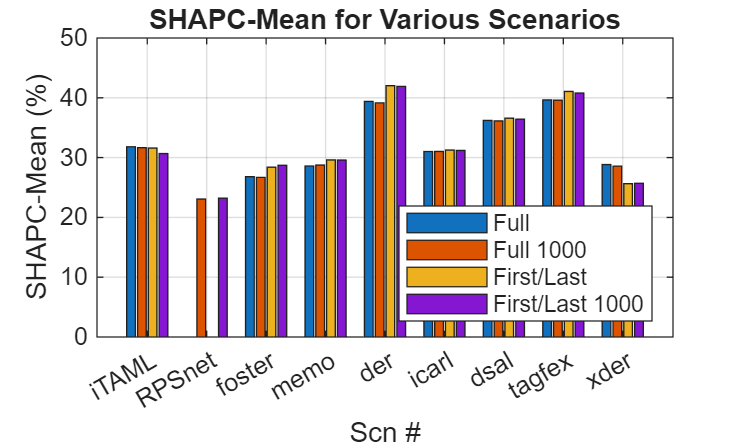

% Create Graph
%{
Y = [full_shapcs'; first_last_shapcs'; 
    full_1000_shapcs'; first_last_1000_shapcs'];
bar(columns, Y)
legend(algs, 'Location', 'southeast')
%}

%%{
%Y = [];
%for i=1:5
%    Y = [Y; [full_shapcs(i) full_1000_shapcs(i) first_last_shapcs(i) first_last_1000_shapcs(i)]];
%end
x = ["Full" "Full 1000" "First/Last" "First/Last 1000"];
bar(algs, all_shapcs);
legend(x, 'Location', 'southeast')
title('SHAPC-Mean for Various Scenarios');
xlabel('Scn #');
ylabel('SHAPC-Mean (%)');

grid on

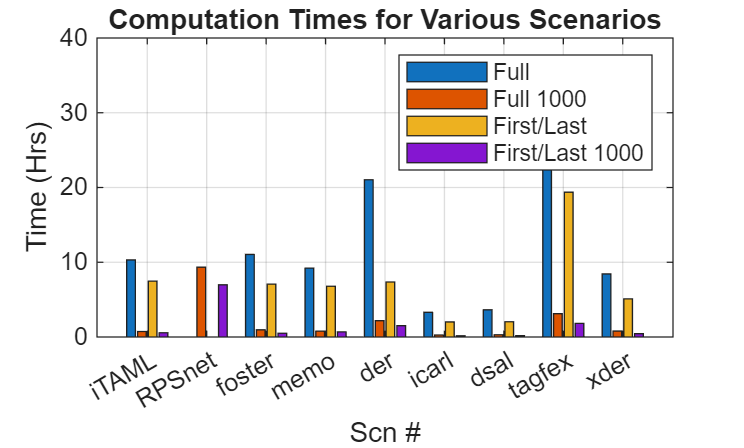


%Y = [];
%for i=1:5
%    Y = [Y; [full_times(i) full_1000_times(i) first_last_times(i) first_last_1000_times(i)]];
%end
x = ["Full" "Full 1000" "First/Last" "First/Last 1000"];
bar(algs, all_times);
legend(x);%, 'Location', 'southeast')
title('Computation Times for Various Scenarios');
xlabel('Scn #');
ylabel('Time (Hrs)');

grid on

% Standard Deviation
std_devs = std(all_shapcs')';
std_dev_table = table(std_devs, 'RowNames', rows)

std_dev_table = 9×1 table
              std_devs
              ________

    iTAML     0.51719 
    RPSnet        NaN 
    foster     1.0503 
    memo      0.53641 
    der         1.561 
    icarl      0.1224 
    dsal      0.21124 
    tagfex    0.76308 
    xder       1.7564 


%{
%Create Hatch Pattern
Y_hatch = Y;
Y_hatch(:,2) = NaN;
Y_hatch(:,4) = NaN;
bar(algs, Y)
%legend(columns, 'Location', 'southeast')

hold on;
b_hatch = bar(algs, Y_hatch);

% 5. Apply the hatch pattern
b_hatch.Pattern = 'crosshatch'; % Apply a pattern
b_hatch.FaceColor = 'none'; % Makes the original bar's color visible
b_hatch.EdgeColor = 'black'; % Optional: change hatch line color

hold off; % Release the hold

%}